# Markov Model: Finding an Equilibrium of State Probabilities

Imagine observing the initial probabilities of finding a system in one of three states. For example, we might seek to model the succession dynamics for a desert plant community in which a patch of land might be dominated by shrublike plants, grasses, or bare land ( $X_t=1, X_t=2,\text{ or }X_t=3$).  If we divided a study site into a grid and observed that 69% of the patches in the grid were initially dominated by shrubs, 13% of the patches were initially dominated by grasses, and 18% were initially covered with bare land, then we might summarize that data with the following state vector.

P=[0.69; 0.13; 0.18];

Now we define a transition matrix for a markov model that describes successinon dynamics for each patch of land.  

Let $P(X_t=1)$, $P(X_t=2 )$, and $P(X_t=3 )$ represent the probabilities that the patch of land is dominated by each of the three states at time $t$. Increment time forward from $t$ by a discrete step to $t + 1$. Predict $P(X_{t+1}=1)$, $P(X_{t+1}=2)$, and $P(X_{t+1}=3)$ (the probabilities that the patch of land will be dominated by each of three states at time $t + 1$) given knowledge of the same probabilities at time $t$.

Do so by invoking the law of total probability:


$$P(X_{t+1}=1) = P(X_{t+1}=1 | X_t=1)P(X_t=1) + P(X_{t+1}=1 | X_t=2)P(X_t=2) + P(X_{t+1}=1 | X_t=3)P(X_t=3)$$



$$P(X_{t+1}=2) = P(X_{t+1}=2 | X_t=1)P(X_t=1) + P(X_{t+1}=2 | X_t=2)P(X_t=2) + P(X_{t+1}=2 | X_t=3)P(X_t=3)$$



$$P(X_{t+1}=3) = P(X_{t+1}=3 | X_t=1)P(X_t=1) + P(X_{t+1}=3 | X_t=2)P(X_t=2) + P(X_{t+1}=3 | X_t=3)P(X_t=3)$$


This may be written as a matrix equation.


$$\left(\begin{array}{c}P(X_{t+1}=1)\\P(X_{t+1}=2)\\P(X_{t+1}=3)\end{array}\right)=\left(\begin{array}{ccc}P(X_{t+1}=1 | X_t=1) & P(X_{t+1}=1 | X_t=2) & P(X_{t+1}=1 | X_t=3)\\
P(X_{t+1}=2 | X_t=1) & P(X_{t+1}=2 | X_t=2) & P(X_{t+1}=2 | X_t=3)\\
P(X_{t+1}=3 | X_t=1) & P(X_{t+1}=3 | X_t=2) & P(X_{t+1}=3 | X_t=3) \end{array}\right)\cdot\left(\begin{array}{c}P(X_{t}=1)\\P(X_{t}=2)\\P(X_{t}=3) \end{array} \right)$$
 

The matrix in this equation is the transition matrix. Its columns are probabilities that must sum to 1. Each entry represents the probability that the system will make a transition from the state corresponding to the column the entry is in at time $t$ to the state that corresponds to the row the entry is in at the future time $t+1$. For instance, valid values might be

M=[
    0.70 0.25 0.11;
    0.14 0.63 0.04;
    0.16 0.12 0.85
    ]

M =     0.7000    0.2500    0.1100
    0.1400    0.6300    0.0400
    0.1600    0.1200    0.8500


With an initial state vector and a transition matrix in place, it is possible to iterate the model in order to see how we expect the distribution of dominant vegetation to behave over time at the study site.

%iterate the model
for i=1:50
    P=[P M*P(:,end)];
end

This gives us a sequence of state vectors.  We may visualize them over time.

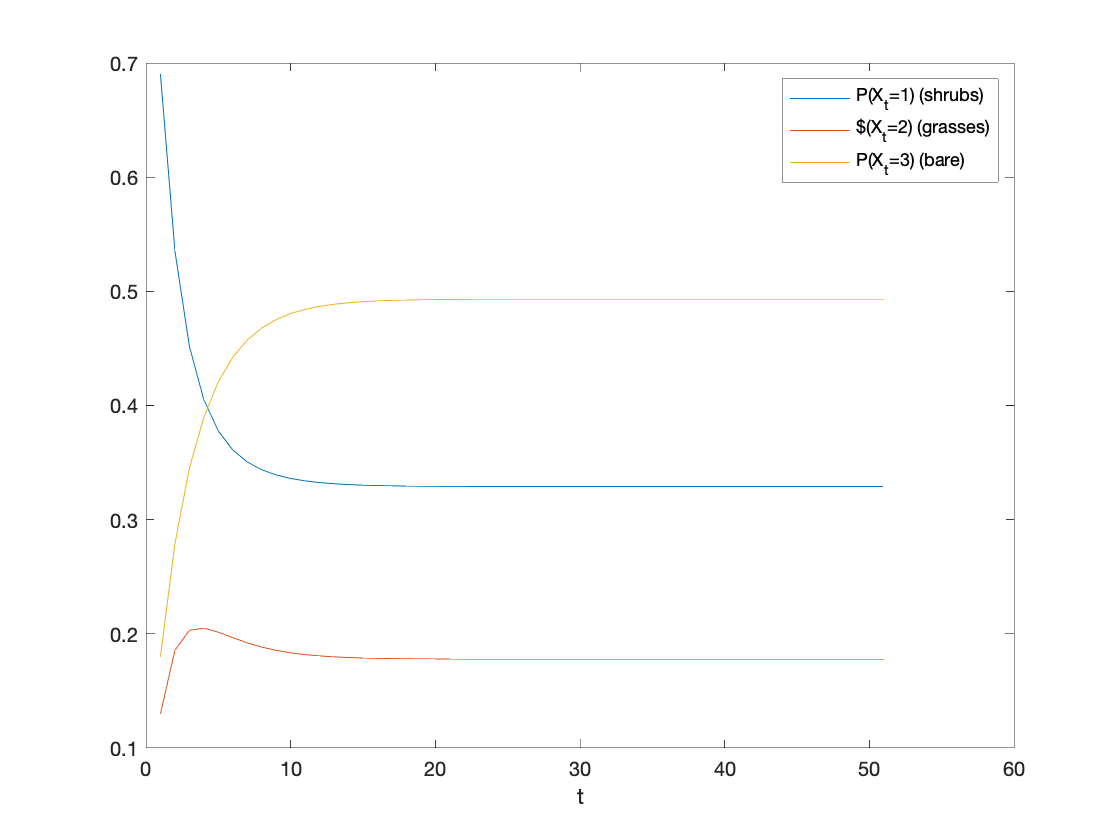

%visualize 
figure(1)
plot(P')
legend('P(X_t=1) (shrubs)','P(X_t=2) (grasses)','P(X_t=3) (bare)')
xlabel('t')